**ECE537 Programming Assignment 3**

Yuan Sui

1a) Plot random process Z(t) with fixed number of steps n = 500, and N = 50 traces

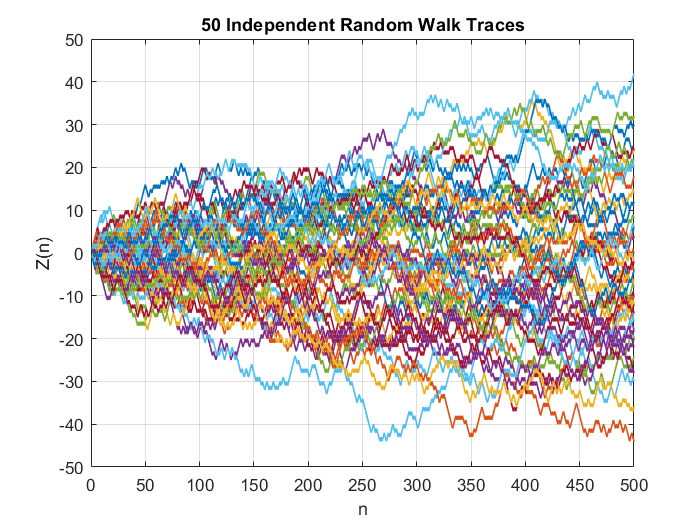

% Parameters
n = 500;        % Number of steps
p = 0.5;        % Probability P(Xi = 1)
num_traces = 50; % Number of random walk traces

% Preallocate matrix to store all traces
Z = zeros(num_traces, n);

% Generate random walk traces
for k = 1:num_traces
    % Generate Xi: 1 with probability p, -1 with probability 1-p
    Xi = 2 * (rand(1, n) < p) - 1;
    % Calculate Z(n) by cumulative sum of Xi
    Z(k, :) = cumsum(Xi);
end

% Plot all traces
figure;
plot(1:n, Z, 'LineWidth', 1.0);
xlabel('n');
ylabel('Z(n)');
title('50 Independent Random Walk Traces');
grid on;

1b)c) Estimate the expected value and variance of Z(n) as a function of n.

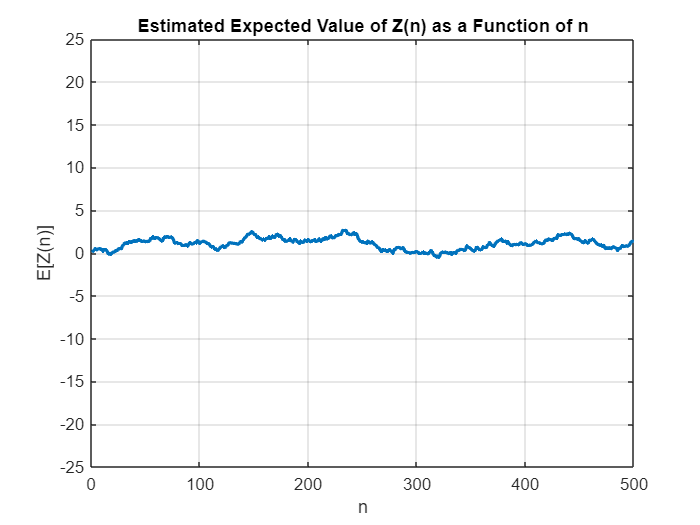

% Parameters
n = 500;        % Number of steps
p = 0.5;        % Probability P(Xi = 1)
num_traces = 50; % Number of random walk traces

% Preallocate matrix to store all traces
Z = zeros(num_traces, n);

% Generate random walk traces
for k = 1:num_traces
    % Generate Xi: 1 with probability p, -1 with probability 1-p
    Xi = 2 * (rand(1, n) < p) - 1;
    % Calculate Z(n) by cumulative sum of Xi
    Z(k, :) = cumsum(Xi);
end

% Calculate the expected value of Z(n) at each n
expected_Z = mean(Z, 1); % Average over all traces

% Plot the expected value
figure;
plot(1:n, expected_Z, 'LineWidth', 2);
xlabel('n');
ylabel('E[Z(n)]');
title('Estimated Expected Value of Z(n) as a Function of n');
grid on;
ylim([-25 25]); % Set y-limits for better visibility

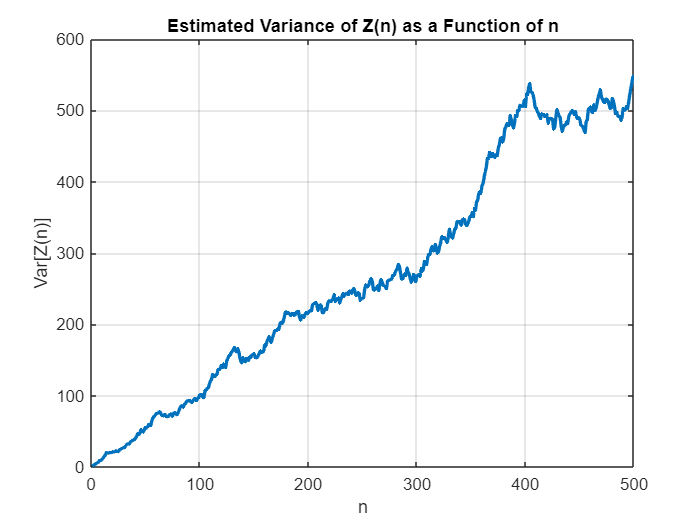

% Parameters
n = 500;        % Number of steps
p = 0.5;        % Probability P(Xi = 1)
num_traces = 50; % Number of random walk traces

% Preallocate matrix to store all traces
Z = zeros(num_traces, n);

% Generate random walk traces
for k = 1:num_traces
    % Generate Xi: 1 with probability p, -1 with probability 1-p
    Xi = 2 * (rand(1, n) < p) - 1;
    % Calculate Z(n) by cumulative sum of Xi
    Z(k, :) = cumsum(Xi);
end

% Calculate the variance of Z(n) at each n
variance_Z = var(Z, 0, 1); % Variance across all traces

% Plot the variance
figure;
plot(1:n, variance_Z, 'LineWidth', 2);
xlabel('n');
ylabel('Var[Z(n)]');
title('Estimated Variance of Z(n) as a Function of n');
grid on;
xlim([0 500]); % Set y-limits for better visibility

Observation: We expect that with p=0.5, the expected value of Z(n) is 0 for all values of n, and the variance of Z(n) to increase linearly as n increases. This makes sense as the possibility of taking +1 step is the same as taking -1 step. Thus, the expected value will be the same but the variance will increases as more steps are taken. 

1d) repeat with p = 0.6

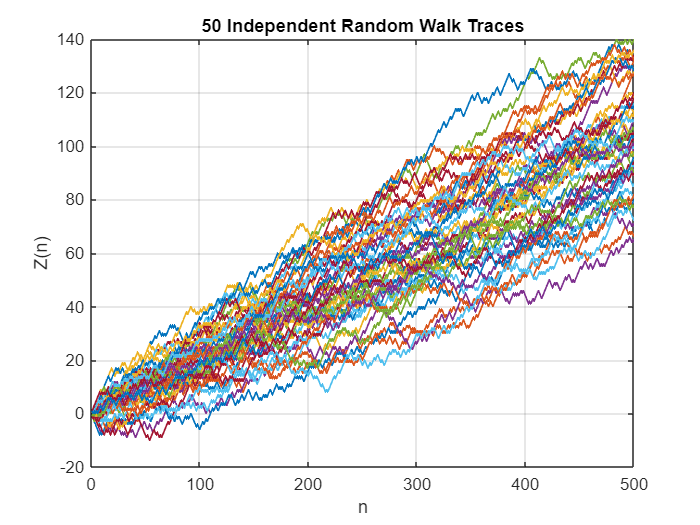

% Parameters
n = 500;        % Number of steps
p = 0.6;        % Probability P(Xi = 1)
num_traces = 50; % Number of random walk traces

% Preallocate matrix to store all traces
Z = zeros(num_traces, n);

% Generate random walk traces
for k = 1:num_traces
    % Generate Xi: 1 with probability p, -1 with probability 1-p
    Xi = 2 * (rand(1, n) < p) - 1;
    % Calculate Z(n) by cumulative sum of Xi
    Z(k, :) = cumsum(Xi);
end

% Plot all traces
figure;
plot(1:n, Z, 'LineWidth', 1.0);
xlabel('n');
ylabel('Z(n)');
title('50 Independent Random Walk Traces');
grid on;

1e) repeat with p = 0.4

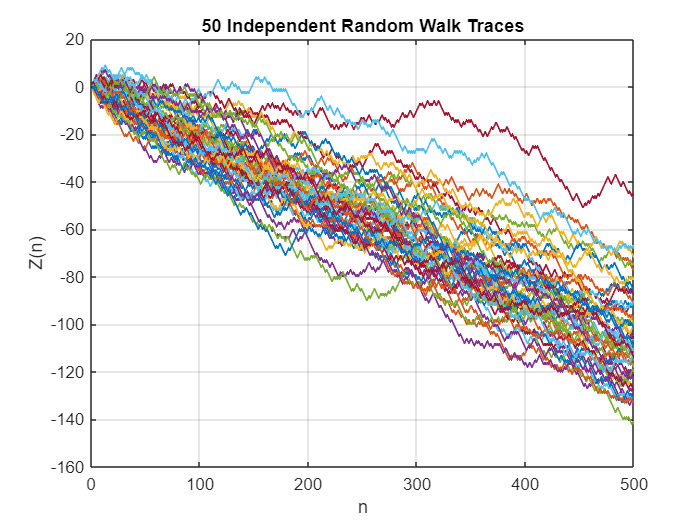

% Parameters
n = 500;        % Number of steps
p = 0.4;        % Probability P(Xi = 1)
num_traces = 50; % Number of random walk traces

% Preallocate matrix to store all traces
Z = zeros(num_traces, n);

% Generate random walk traces
for k = 1:num_traces
    % Generate Xi: 1 with probability p, -1 with probability 1-p
    Xi = 2 * (rand(1, n) < p) - 1;
    % Calculate Z(n) by cumulative sum of Xi
    Z(k, :) = cumsum(Xi);
end

% Plot all traces
figure;
plot(1:n, Z, 'LineWidth', 1.0);
xlabel('n');
ylabel('Z(n)');
title('50 Independent Random Walk Traces');
grid on;

Observation: We can see that after we change the possibility of taking +1 and -1 no longer unbiased, the behavior of the traces also becomes different. In the first case 1d) where p = 0.6, it is more likely to take a +1 step, therefore the traces are increasing as n increases. In the second case 1e) where p = 0.4, it is more likely to take a -1 step, therefore the traces are decreasing as n increaes. 

2a)  Plot 5 traces of random process N(t) which is identifier function with summation of exponentially distributed random variable as the predicate. 

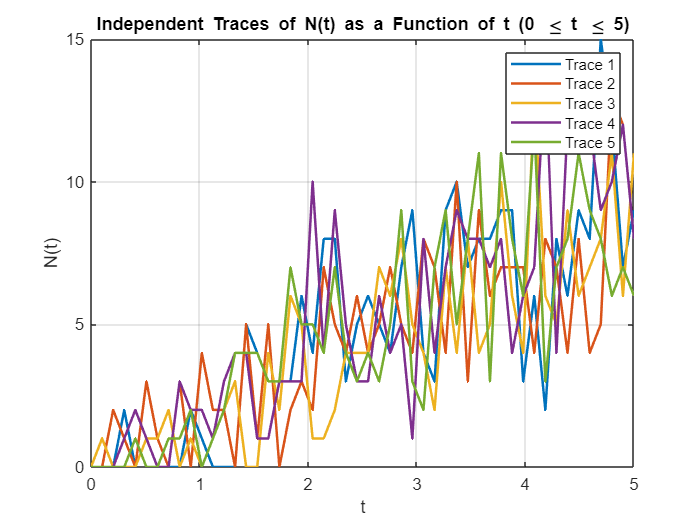

% Parameters
lambda = 2;             % Parameter of the exponential distribution
t_values = linspace(0, 5, 50); % Range of t values from 0 to 5
num_traces = 5;         % Number of traces
max_n = 100;            % Maximum number of random variables to sum

% Preallocate matrix to store N(t) traces
N_t = zeros(num_traces, length(t_values));

% Generate traces of N(t)
for k = 1:num_traces
% For the current value of S_n, evaluate N(t) for all t_values
    N_t_k = zeros(1,length(t_values));
    for j = 1:length(t_values)
        Sn = 0; % Initialize S_n
        value = 0;
        for n = 1:max_n
            % Generate an exponential random variable
            Xi = exprnd(1/lambda);
            Sn = Sn + Xi; % Update the cumulative sum

            % Evaluate the identifier function for the current t value
            if Sn < t_values(j)
                value = value+1; % Condition is true
            end
        end
        N_t_k(j)=value;

    end
    N_t(k,:)= N_t_k;
end

% Plot the traces
figure;
plot(t_values, N_t', 'LineWidth', 1.5);
xlabel('t');
ylabel('N(t)');
title('Independent Traces of N(t) as a Function of t (0 \leq t \leq 5)');
legend(arrayfun(@(x) sprintf('Trace %d', x), 1:num_traces, 'UniformOutput', false));
grid on;

% Identifier function

2b) Plot histogram of the 1000 traces of N(t) and plot the PDF of poisson distribution 

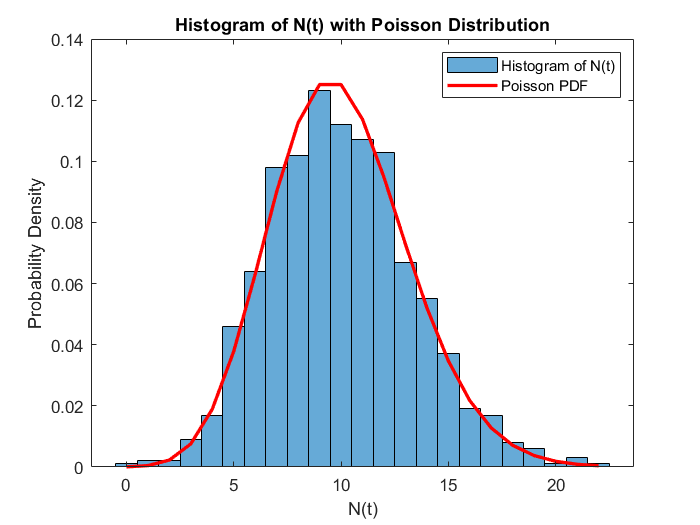

% Parameters
lambda = 2;             % Parameter of the exponential distribution
t = 5;                  % Fixed t value
num_traces = 1000;      % Number of traces

% Preallocate vector to store N(t) values
N_t_values = zeros(1, num_traces);

% Generate traces of N(t)
for k = 1:num_traces
    Sn = 0; % Initialize S_n
    value = 0; % Initialize N(t)
    while Sn < t
        % Generate an exponential random variable
        Xi = exprnd(1/lambda);
        Sn = Sn + Xi; % Update the cumulative sum
        if Sn < t
            value = value + 1; % Increment if condition holds
        end
    end
    N_t_values(k) = value;
end

% Plot histogram of N(t) values
figure;
histogram(N_t_values, 'Normalization', 'pdf');
hold on;

% Poisson distribution with mean lambda*t
mean_poisson = lambda * t;
x = 0:max(N_t_values); % Values to evaluate the Poisson pdf
poisson_pdf = poisspdf(x, mean_poisson);

% Plot the Poisson pdf
plot(x, poisson_pdf, 'r-', 'LineWidth', 2);
title('Histogram of N(t) with Poisson Distribution');
xlabel('N(t)');
ylabel('Probability Density');
legend('Histogram of N(t)', 'Poisson PDF');
hold off;

2c)d) Compare the expected value and variance of N(t) between generated data and theoretical value

% Estimate expected value and variance from generated data
estimated_mean = mean(N_t_values);
estimated_variance = var(N_t_values);

% Theoretical values
theoretical_mean = lambda * t;
theoretical_variance = lambda * t;

% Display results
fprintf('Estimated Mean: %.2f\n', estimated_mean);

Estimated Mean: 10.01


fprintf('Theoretical Mean: %.2f\n', theoretical_mean);

Theoretical Mean: 10.00


fprintf('Estimated Variance: %.2f\n', estimated_variance);

Estimated Variance: 11.09


fprintf('Theoretical Variance: %.2f\n', theoretical_variance);

Theoretical Variance: 10.00


As shown value the estimated value and variance of generated data is very similar to the theoretical value of poisson distribution. 

function id = I(Sn, t)
    if Sn < t
        id = 1; % Condition is true
    else
        id = 0; % Condition is false
    end
end